# European Put via Quadrature 

# Improvement 1: Penultimate Step Black-Scholes Smoothing

tic;

function price = european_quad_smooth (S0, K, r, q, sigma, T, n_steps, m_grid)

    % Time-homogeneous grid + efficient implementation:
    % c_t = e^{-r h} * F * ( v_{t+h} ∘ w )
    % where F(i,j) = f(s_j | s_i) and w are Simpson weights on destination grid.
    
    % 1) Time step and log-price grid (fixed for all steps)
    h  = 1/365;                 
    s0 = log(S0);
    
    % wide enough to capture prob. mass through T 
    smin = s0 - 10*(sigma*sqrt(T));
    smax = s0 + 10*(sigma*sqrt(T));
    
    % uniform log-price grid
    s = linspace(smin, smax, m_grid)';            % m x 1
    ds = s(2) - s(1);
    S = exp(s);
    mid = (m_grid+1)/2;                            % assume m_grid odd
    
    % 2) One-step transition density in log-space (GBM -> Normal)
    mu_shift = (r - q - 0.5*sigma^2) * h;
    sig_h    = sigma * sqrt(h);
    
    F = zeros(m_grid, m_grid);
    dest = s';                                     % 1 x m (destination axis)
    
    for i = 1:m_grid
        mu_i   = s(i) + mu_shift;                  % mean of s_{t+h} | s_t = s(i)
        z      = (dest - mu_i) / sig_h;
        F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*(z.^2));   % row i pdf values
    end
    
    % 3) Simpson weights 
    w = ones(m_grid,1);
    w(2:2:end-1) = 4;
    w(3:2:end-2) = 2;
    w = w * (ds/3);                              
    
    % 4) Penultimate-step smoothing (Black–Scholes with maturity h)
    d1  = (log(S./K) + (r - q + 0.5*sigma^2)*h) / (sigma*sqrt(h));
    d2  = d1 - sigma*sqrt(h);
    Nd1 = 0.5*(1 + erf(d1/sqrt(2)));
    Nd2 = 0.5*(1 + erf(d2/sqrt(2)));
    A_put = K*exp(-r*h).*(1 - Nd2) - S.*exp(-q*h).*(1 - Nd1);   
    
    v_next = A_put;                               % start recursion at T-h
    disc   = exp(-r*h);
    
    % 5) Backward propagation: pure continuation (European, no max)
    for t = 2:n_steps
        % c_t = e^{-r h} * F * ( v_{t+h} ∘ w )
        v_next = disc * ( F * (v_next .* w) );
    end
    
    % time-0 price at S0 (center node)
    price = v_next(mid);
end

% Run Euro
S0 = 50;  K = 50;
r = 0.05; q = 0.02; sigma = 0.30;
T = 60/365;              
n_steps = 60;            
m_grid  = 401;           

peuro = european_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('European put (quadrature, T-h smoothing): %.6f\n', peuro);

European put (quadrature, T-h smoothing): 2.290222



toc;

Elapsed time is 0.085906 seconds.


## European Put: Convergence Plots & Table (Simonato quadrature with T−h smoothing)

S0 = 50;    
r  = 0.05;  
q  = 0.02;
sigma = 0.30;

m_list = 101:2:401;    % Odd grid sizes so s0 sits at center node... need this for simpson, now burned into our brains from the quiz lol
n_steps_short = 60;    % 60-day case
n_steps_long  = 365;   % 365-day case

## Plots:

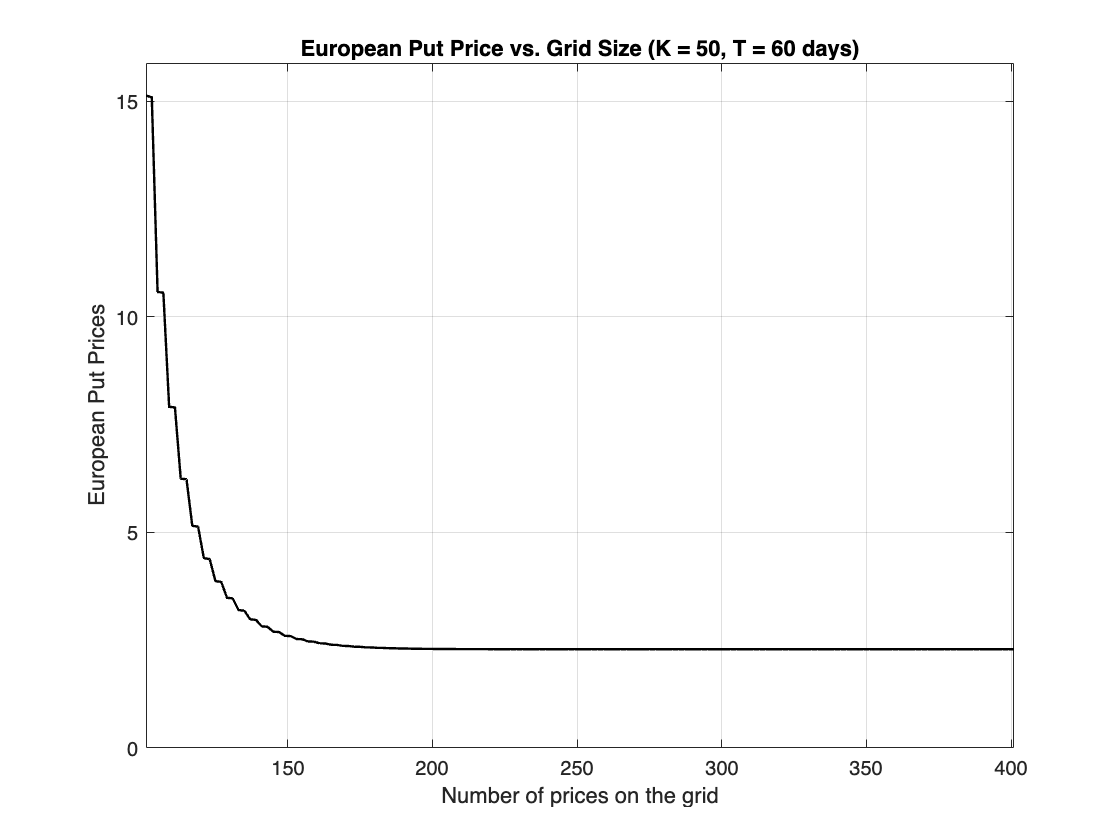

% 1) K = 50, T = 60 days
K = 50;  T = 60/365;
prices_K50_60 = nan(size(m_list));
for k = 1:numel(m_list)
    m_grid = m_list(k);
    prices_K50_60(k) = european_quad_smooth(S0,K,r,q,sigma,T,n_steps_short,m_grid);
end

% 2) K = 45, T = 60 days
K = 45;  T = 60/365;
prices_K45_60 = nan(size(m_list));
for k = 1:numel(m_list)
    m_grid = m_list(k);
    prices_K45_60(k) = european_quad_smooth(S0,K,r,q,sigma,T,n_steps_short,m_grid);
end

% Shared y-axis for T = 60 days (start at 0)
ymin_60 = 0;
ymax_60 = max([prices_K50_60(:); prices_K45_60(:)]) * 1.05;

% Plot K=50, T=60
figure; hold on; box on;
plot(m_list, prices_K50_60, 'k-', 'LineWidth', 1.2);
xlabel('Number of prices on the grid','FontSize',11);
ylabel('European Put Prices','FontSize',11);
title('European Put Price vs. Grid Size (K = 50, T = 60 days)', 'FontWeight','bold');
xlim([min(m_list) max(m_list)]);
ylim([ymin_60 ymax_60]);
grid on;

## Table (K = 50):

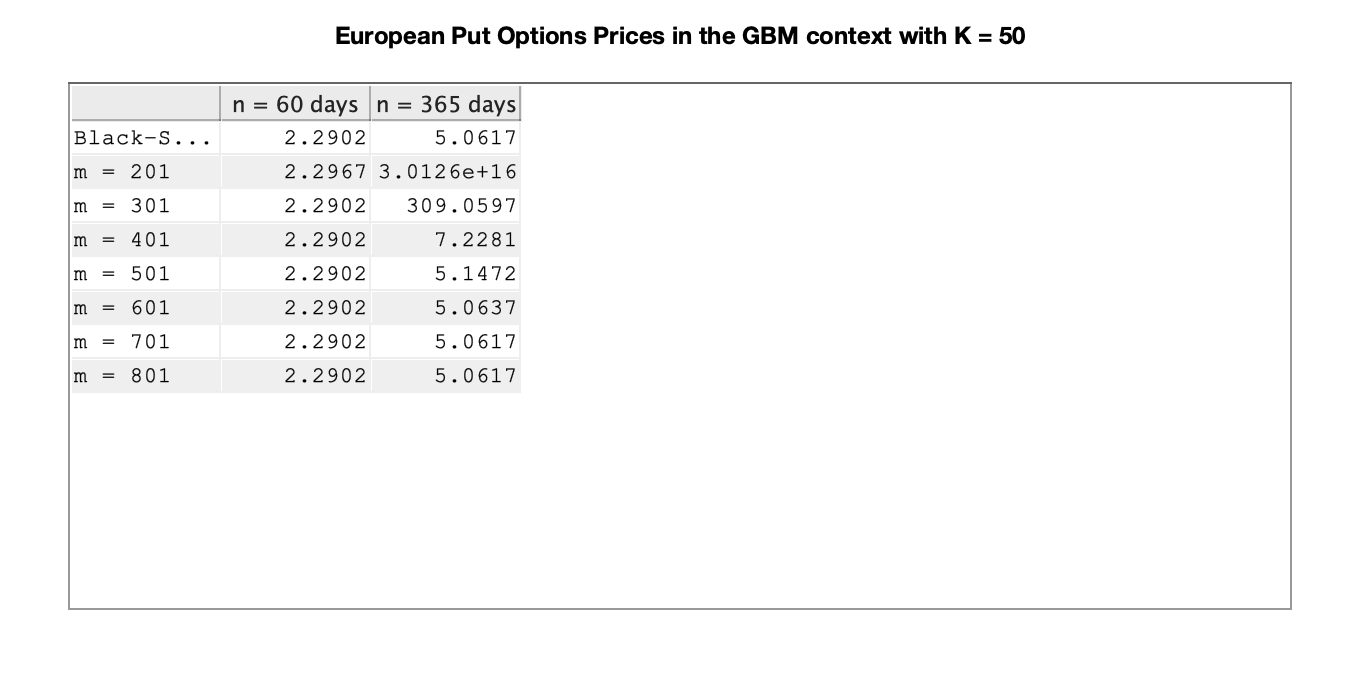

S0 = 50; K = 50; r = 0.05; q = 0.02; sigma = 0.30;

m_vec   = [201 301 401 501 601 701 801]';
T_60    = 60/365;   n_60   = 60;
T_365   = 365/365;  n_365  = 365;

% Quadrature European (Function)
euro_60  = nan(numel(m_vec),1);
euro_365 = nan(numel(m_vec),1);
for j = 1:numel(m_vec)
    m = m_vec(j);
    euro_60(j)  = european_quad_smooth(S0,K,r,q,sigma,T_60, n_60,  m);
    euro_365(j) = european_quad_smooth(S0,K,r,q,sigma,T_365,n_365, m);
end
euro_60_disp  = round(euro_60,  4);
euro_365_disp = round(euro_365, 4);

% Hard-coded Black–Scholes European reference values (paper, K = 50)
BS_60  = 2.2902;
BS_365 = 5.0617;

% Build data: first row BS reference, then quadrature rows
data = cell(numel(m_vec)+1, 3);
data{1,1} = 'Black–Scholes Prices';
data{1,2} = BS_60;
data{1,3} = BS_365;
for j = 1:numel(m_vec)
    data{j+1,1} = sprintf('m = %d', m_vec(j));
    data{j+1,2} = euro_60_disp(j);
    data{j+1,3} = euro_365_disp(j);
end

% Create table window
f = figure('Name','European Put Options Prices in the GBM context with K = 50',...
           'NumberTitle','off','Position',[200 200 680 340],'Color','white');

annotation(f,'textbox',[0 0.90 1 0.08],...
    'String','European Put Options Prices in the GBM context with K = 50',...
    'EdgeColor','none','HorizontalAlignment','center',...
    'FontWeight','bold','FontSize',12);

colnames = {'','n = 60 days','n = 365 days'};
uitable(f,'Data',data,'ColumnName',colnames,'RowName',[],...
    'ColumnEditable',[false false false],'Units','normalized',...
    'Position',[0.05 0.10 0.90 0.78],'FontName','Courier','FontSize',11);

## Comparison:

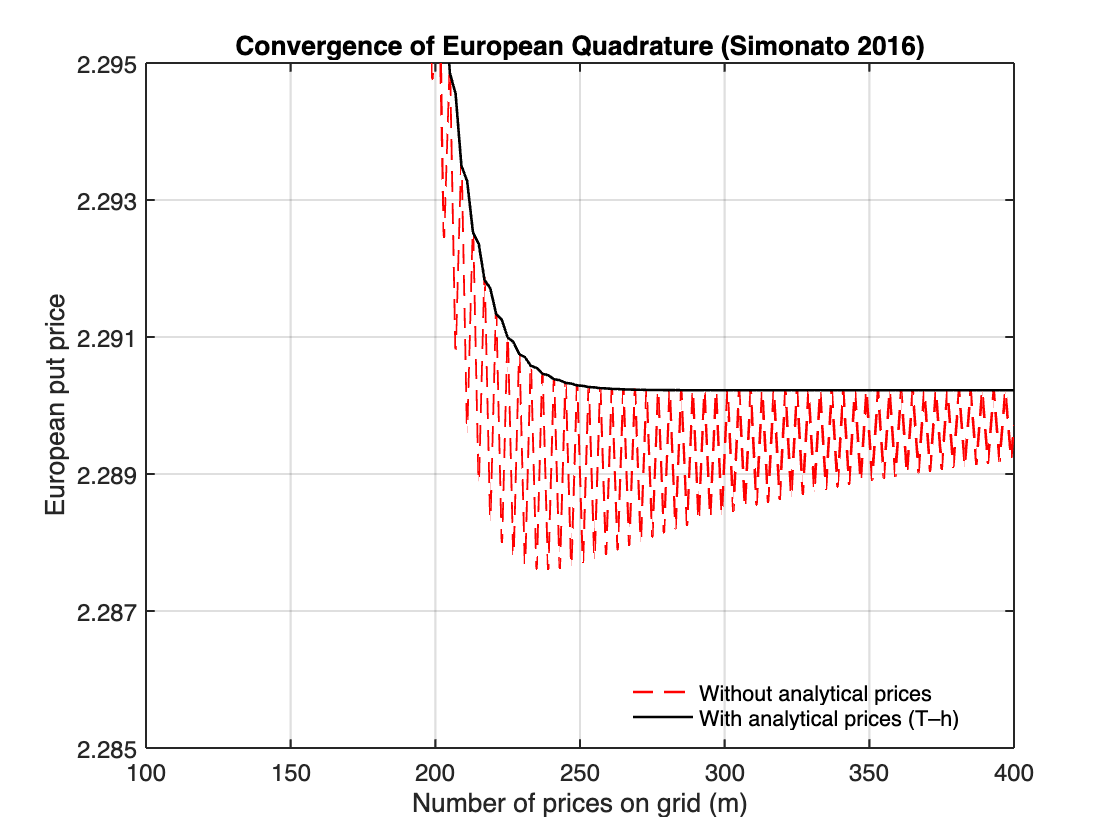

function price = european_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid)
    % Time step and grid 
    h   = T / n_steps;
    s0  = log(S0);
    smin = s0 - 10*sigma*sqrt(T);
    smax = s0 + 10*sigma*sqrt(T);
    s    = linspace(smin,smax,m_grid)'; 
    S    = exp(s);
    mid  = ceil(m_grid/2);
    ds   = s(2) - s(1);

    % Simpson weights (1 4 2 4 ... 2 4 1)
    w = ones(m_grid,1);
    w(2:2:end-1)=4; w(3:2:end-2)=2;
    w = w*(ds/3);

    % Terminal payoff 
    v_next = max(K - S, 0);
    disc   = exp(-r*h);

    % Backward recursion
    for t = 1:n_steps
        % recompute transition density each step (inefficient)
        mu_shift = (r - q - 0.5*sigma^2)*h;
        sig_h    = sigma*sqrt(h);
        F = zeros(m_grid);
        for i = 1:m_grid
            mu_i = s(i) + mu_shift;
            z = (s' - mu_i)/sig_h;
            F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*z.^2);
        end
        % continuation value (no max)
        v_next = disc * (F * (v_next .* w));
    end

    price = v_next(mid);
end

clear; clc;

S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
m_list = 101:2:m_grid;

prices_naive  = nan(size(m_list));
prices_smooth = nan(size(m_list));

for k = 1:numel(m_list)
    prices_naive(k)  = european_quad_naive(S0,K,r,q,sigma,T,n_steps,m_list(k));
    prices_smooth(k) = european_quad_smooth(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

figure; hold on; box on;
plot(m_list, prices_naive,  'r--','LineWidth',1.3);
plot(m_list, prices_smooth, 'k-','LineWidth',1.3);
legend('Without analytical prices','With analytical prices (T–h)');
xlabel('Number of prices on grid (m)');
ylabel('European put price');
title('Convergence of European Quadrature (Simonato 2016)');
grid on;
xlim([100 400]);
ylim([2.285 2.295]);
yticks(2.285:0.002:2.295);
set(gca,'FontSize',12,'LineWidth',1.1);
legend('Location','best','Box','off');